%Define Sample Frequency
Fs=44100;
%Define Recording Length (seconds)
L=5;
% Create audiorecorder object
recObj = audiorecorder(Fs, 16, 1)

recObj =   audiorecorder with properties:

          SampleRate: 44100
       BitsPerSample: 16
    NumberOfChannels: 1
            DeviceID: -1
       CurrentSample: 1
        TotalSamples: 0
             Running: 'off'
            StartFcn: []
             StopFcn: []
            TimerFcn: []
         TimerPeriod: 0.0500
                 Tag: ''
            UserData: []
                Type: 'audiorecorder'



%Record for L seconds
disp('Start Recording.');

Start Recording.


recordblocking(recObj, L);
disp('End of Recording.');

End of Recording.


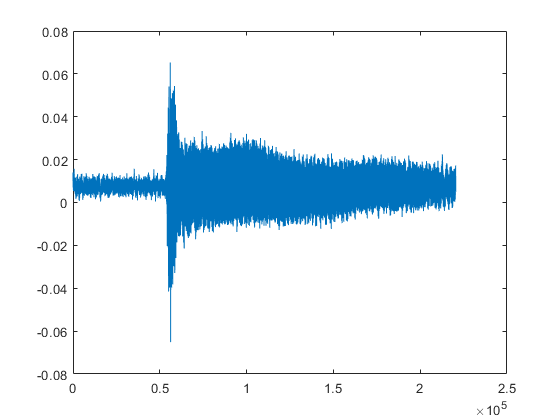


%Play Recording
%play(recObj);

%Store Data in array
y = getaudiodata(recObj);
%Plot Data
plot(y);

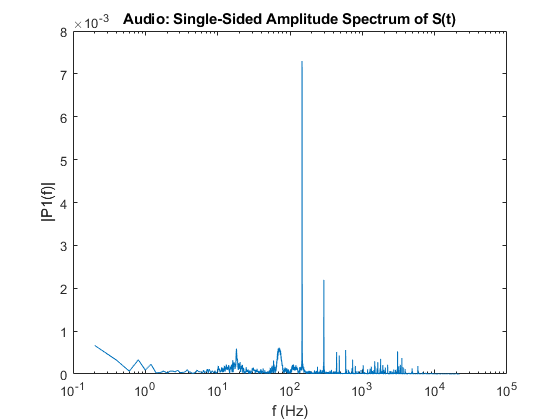

%Perform FFT Analysis
%Calculate time values
tt=linspace(0,L,length(y));

%Compute FFT
Y=fft(y);
L=Fs*L;

P2 = abs(Y/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);

%Define frequency domain and plot
f = Fs*(0:(L/2))/L;
semilogx(f,P1) 
title('Audio: Single-Sided Amplitude Spectrum of S(t)')
xlabel('f (Hz)')
ylabel('|P1(f)|')

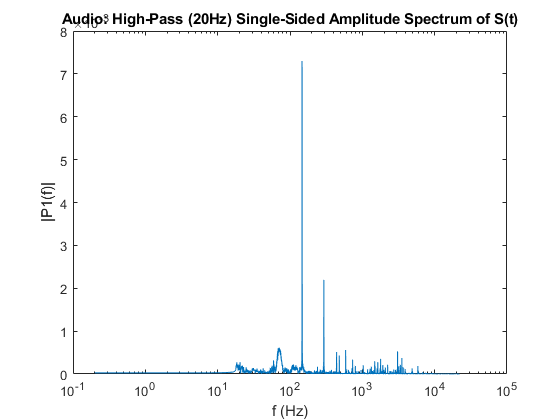


%Filter signal (Highpass 20 Hz)
highpass_20Hz_y = highpass(y,20,Fs);
%Compute filtered FFT
highpass_20Hz_Y=fft(highpass_20Hz_y);
highpass_20Hz_P2 = abs(highpass_20Hz_Y/L);
highpass_20Hz_P1 = highpass_20Hz_P2(1:L/2+1);
highpass_20Hz_P1(2:end-1) = 2*highpass_20Hz_P1(2:end-1);

semilogx(f,highpass_20Hz_P1) 
title('Audio: High-Pass (20Hz) Single-Sided Amplitude Spectrum of S(t)')
xlabel('f (Hz)')
ylabel('|P1(f)|')